% chenzhe, 2019-09-03
% It is likely useful to manually label twin-gb intersection.  We need some ground truth data anyway.


clear;
addChenFunction;

% grainDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab\Grain_1144_data_for_paper_ppt','Folder to save the grain data'),'\'];
dicPath = uigetdir('D:\WE43_T6_C1_insitu_compression\stitched_DIC','pick DIC directory, which contains the stitched DIC data for each stop');
dicFiles = dir([dicPath,'\*.mat']);
dicFiles = struct2cell(dicFiles);
dicFiles = dicFiles(1,:)';

% looks like have to include this part to read the sample name.
[fileSetting,pathSetting] = uigetfile('','select setting file which contains sampleName, stopNames, FOVs, translations, etc');
load_settings([pathSetting,fileSetting],'sampleName','cpEBSD','cpSEM','sampleMaterial','stressTensor','strainPauses');

% load previous data and settings
saveDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab_after_realign','choose a path of the saved processed data, or WS, or etc.'),'\'];
saveDataPathInput = saveDataPath;
load([saveDataPath,sampleName,'_traceAnalysis_WS_settings.mat']);
if ~strcmpi(saveDataPath,saveDataPathInput)
    disp('Input saveDataPath is different from that saved in setting.mat file. Check files or code.');
    return;
end

% Load from the pre-labeled results: twinMap, sfMap, struCell.  (cToGbDistMap is omitted, as will no longer be used in this code)
[confirmedLabelFile, confirmedLabelPath] = uigetfile('D:\p\m\DIC_Analysis\*.mat','select the results where twin identification was based on trace dir and strain');

[twinGbIntersectionFile, twinGbIntersectionPath] = uigetfile('D:\p\m\DIC_Analysis\temp_results\*.mat','select the results for twin-grain boundary intersection');

try
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
catch
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
end
% modify / or keep an eye on these settings for the specific sample to analyze  ------------------------------------------------------------------------------------
STOP = {'0','1','2','3','4','5','6','7'};
B=1;    % 0-based B=1.  1-based B=0.
iE_start = 2;   % elongation levels to analyze. 0-based.
iE_stop = 5;

% file name prefixes
f1 = 'WE43_T6_C1_s';
f2 = '_';

debugTF = 0;

% [data] strain data. Convert into v7.3 for partial loading
clear strainFile;
for iE = iE_start-1:iE_stop
    strainFileName = [dicPath,'\',f2,STOP{iE+B}];
    disp(strainFileName);
    if ~exist([strainFileName,'_v73.mat'],'file')
        load(strainFileName);
        clear('exy_corrected');
        load(strainFileName,'exy_corrected');   % if 'exy_corrected' does not exist, this does not give error, rather, just warning.
        
        if exist('exy_corrected','var')&&(1==exy_corrected)
            disp('================= exy already corrected ! ========================');
            exy_corrected = 1;
        else
            disp('================= exy being corrected here ! =======================');
            exy = -exy;
            exy_corrected = 1;
        end
        % remove bad data points
        exx(sigma==-1) = nan;
        exy(sigma==-1) = nan;
        eyy(sigma==-1) = nan;
        qt_exx = quantile(exx(:),[0.0013,0.9987]); qt_exx(1)=min(-1,qt_exx(1)); qt_exx(2)=max(1,qt_exx(2));
        qt_exy = quantile(exy(:),[0.0013,0.9987]); qt_exy(1)=min(-1,qt_exy(1)); qt_exy(2)=max(1,qt_exy(2));
        qt_eyy = quantile(eyy(:),[0.0013,0.9987]); qt_eyy(1)=min(-1,qt_eyy(1)); qt_eyy(2)=max(1,qt_eyy(2));
        ind_outlier = (exx<qt_exx(1))|(exx>qt_exx(2))|(exy<qt_exy(1))|(exy>qt_exy(2))|(eyy<qt_eyy(1))|(eyy>qt_eyy(2));
        exx(ind_outlier) = nan;
        exy(ind_outlier) = nan;
        eyy(ind_outlier) = nan;
        
        outlier_removed = 1;
        save([strainFileName,'_v73.mat'],'outlier_removed','exy_corrected','-v7.3');
        
        myFile = matfile(strainFileName);
        myFields = who(myFile);
        for ii=1:length(myFields)
            save([strainFileName,'_v73.mat'],myFields{ii},'-append','-v7.3');
        end
    else
        disp('v7.3 file already exist');
    end
    strainFile{iE} = matfile([strainFileName,'_v73.mat']);
end

% (0) load data, using SF threshold values to assign active twin system, and make maps
% Load cluster number maps (cleaned).

clusterNumberMapCell = cell(1,length(STOP)-1);
for iE = []%iE_start:iE_stop
    fName_c2t_result = [sampleName,'_s',num2str(STOP{iE+B}),'_cluster_to_twin_result.mat'];
    load([saveDataPath,fName_c2t_result],'clusterNumMapCleaned');
    clusterNumberMapCell{iE} = clusterNumMapCleaned;
end

% Load from the pre-labeled results: twinMapCell, sfMapCell, struCell.  (cToGbDistMapCell is omitted, as will no longer be used in this code)
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'struCell','twinMapCell','trueTwinMapCell','sfMapCell','tNote');
load(fullfile(confirmedLabelPath,confirmedLabelFile),'trueTwinMapCell');

% load previous twin_gb interaction result, for reference.
load(fullfile(twinGbIntersectionPath, twinGbIntersectionFile));


## **Here, load data.**

%% Load data here.

## Summary. To determine twin activation, effect of (1) m' rank, (2) m', (3) resB, (4) resB rank

Objects to compare: twinned variants in twinned grains (1) All twin boundaries (2) Boundaries with intersecting twins (3) Boundaries where twins are considered to be initiated from Properties to compare: (1) m', (2) m' rank, (3) resB, (4) resB rank

## **(0) m' rank**

disp('------------------------------------');

------------------------------------


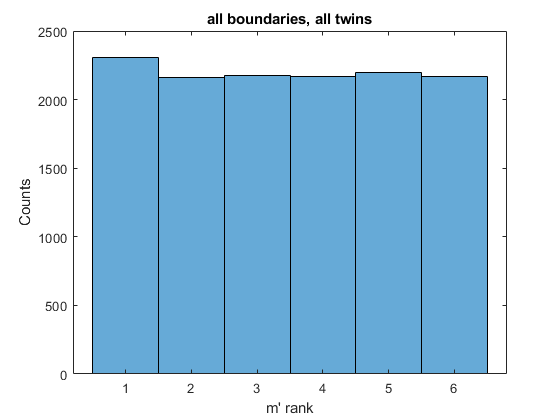

close all;
% (1) all boundaries, distribution of m'
figure;
histogram(T.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('all boundaries, all twins');

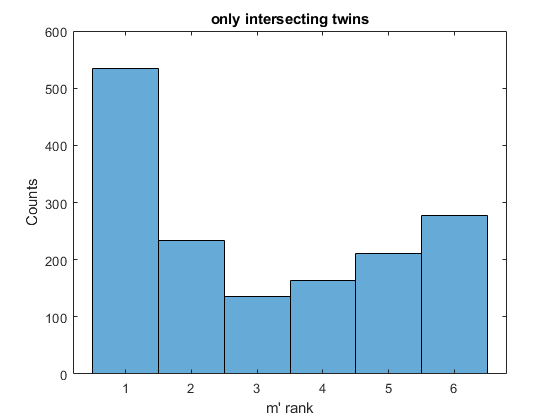


% (2) boundaries with intersecting twins
ind = (T.incoming==1);
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('only intersecting twins');

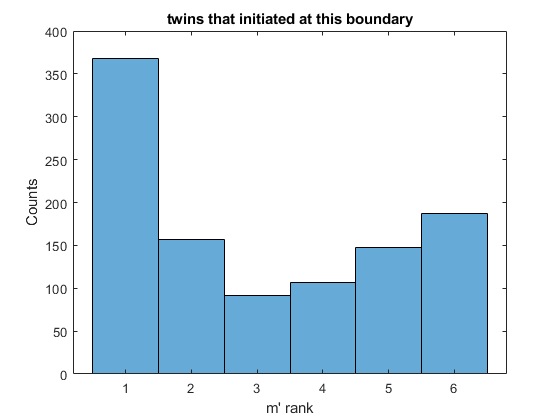


% (3) boundaries with twins that initiated at this boundary
ind = (T.iiE_each_twin_at_this_boundary == T.iiE_each_twin);
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('twins that initiated at this boundary');

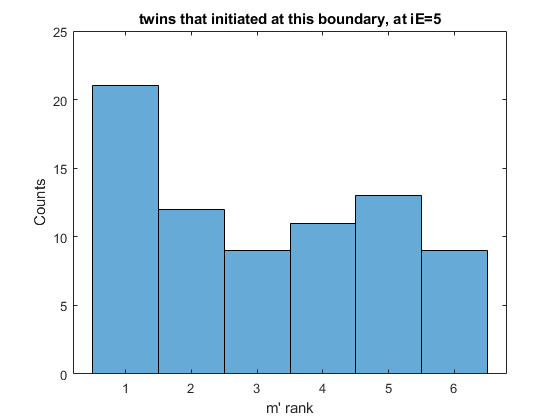


% (4) boundaries with twins that initiated at this boundary, and at this iE
ind = (T.iiE_each_twin_at_this_boundary == T.iiE_each_twin)&(T.iiE_each_twin==iE);
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title(['twins that initiated at this boundary, at iE=',num2str(iE)]);

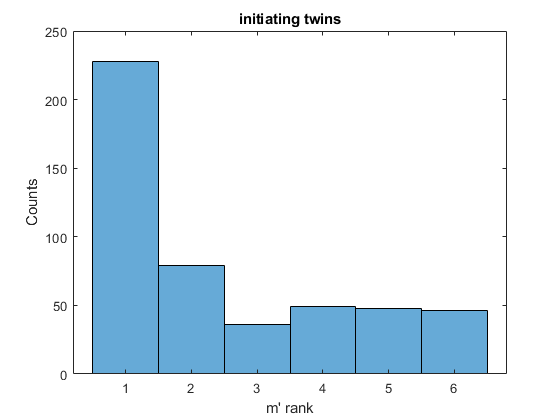


% (5) boundaries with initiating twins (determined by my assumption)
ind = (T.initiating==1);
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('initiating twins');

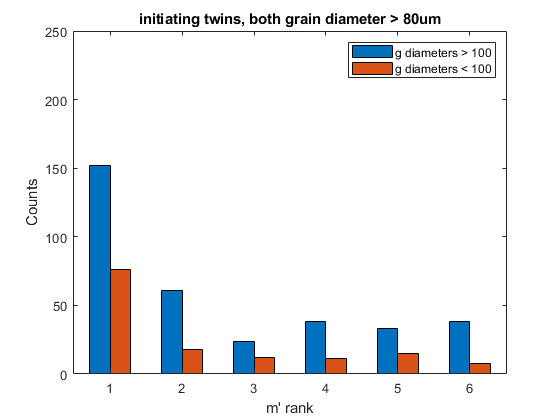

ylim = get(gca,'ylim');

% (6) divide by grain size.  Does large grain show more distinct trend? -->
% Looks like no obvious grain size effect, after manual labeling.   
ind = (T.initiating==1)&(T.gDia>100)&(T.gDia_neighbor>100);
t = T(ind,:);
N1 = histcounts(t.rank_mPrime, 0.5:6.5);
ind = (T.initiating==1)&((T.gDia<100)|(T.gDia_neighbor<100));
t = T(ind,:);
N2 = histcounts(t.rank_mPrime, 0.5:6.5);
figure;
bar(1:6,[N1(:),N2(:)], 1);
xlabel('m'' rank');
ylabel('Counts');
legend({'g diameters > 100', 'g diameters < 100'});
title('initiating twins, both grain diameter > 80um');
set(gca,'ylim',ylim);

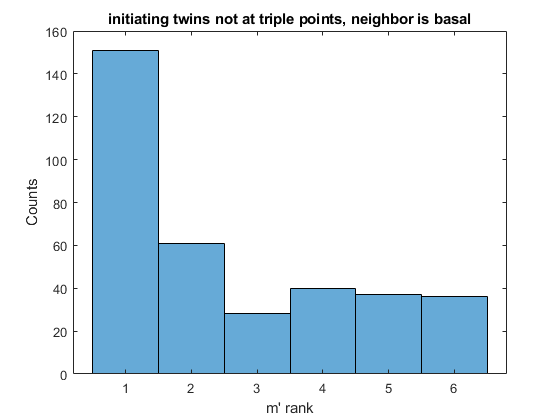


% (7) If only look at those paired with basal slip
ind = (T.incoming==1)&(T.initiating==1)&(ismember(T.ssn_neighbor,[1,2,3]));
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('initiating twins not at triple points, neighbor is basal');

## (1) m'

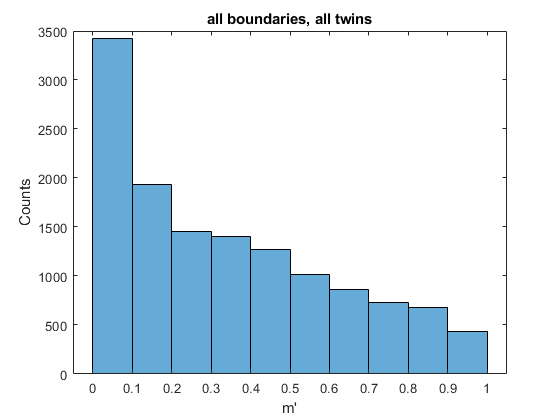

close all;
% (1) all boundaries, distribution of m'
figure;
histogram(T.mPrime, 0:0.1:1);
xlabel('m''');
ylabel('Counts');
title('all boundaries, all twins');

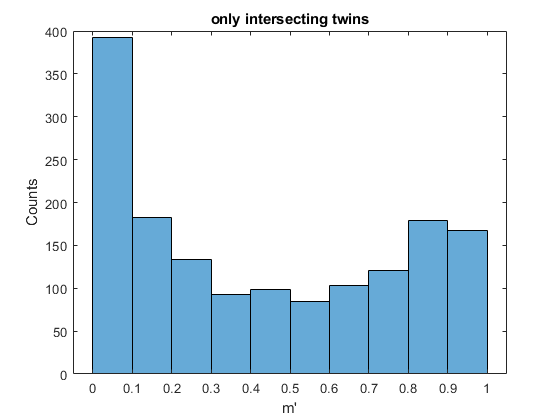


% (2) boundaries with intersecting twins
ind = (T.incoming==1);
t = T(ind,:);
figure;
histogram(t.mPrime, 0:0.1:1);
xlabel('m''');
ylabel('Counts');
title('only intersecting twins');

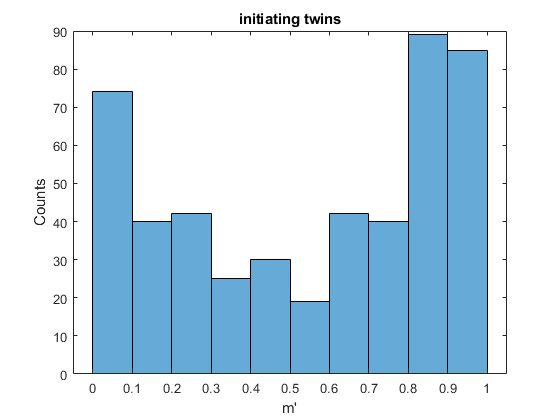


% (3) boundaries with initiating twins (triple points, grain size considered)
ind = (T.incoming==1)&(T.initiating==1);
t = T(ind,:);
figure;
histogram(t.mPrime, 0:0.1:1);
xlabel('m''');
ylabel('Counts');
title('initiating twins');

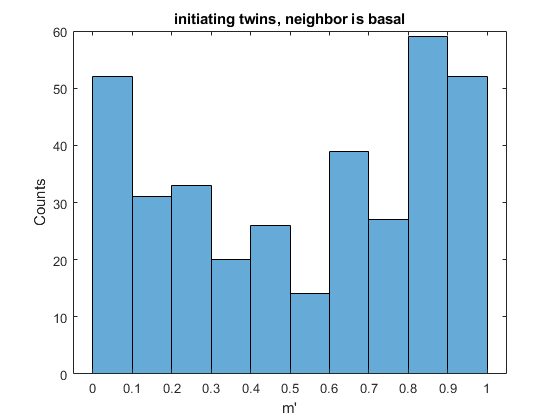


% (4) If only look at those paired with basal slip
ind = (T.incoming==1)&(T.initiating==1)&(ismember(T.ssn_neighbor,[1,2,3]));
t = T(ind,:);
figure;
histogram(t.mPrime, 0:0.1:1);
xlabel('m''');
ylabel('Counts');
title('initiating twins, neighbor is basal');

## (2) m' rank

disp('------------------------------------');

------------------------------------


close all;
% (1) all boundaries, distribution of m'
figure;
histogram(T.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('all boundaries, all twins');


% (2) boundaries with intersecting twins
ind = (T.incoming==1);
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('only intersecting twins');


% (3) boundaries with initiating twins
ind = (T.incoming==1)&(T.initiating==1);
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('initiating twins');

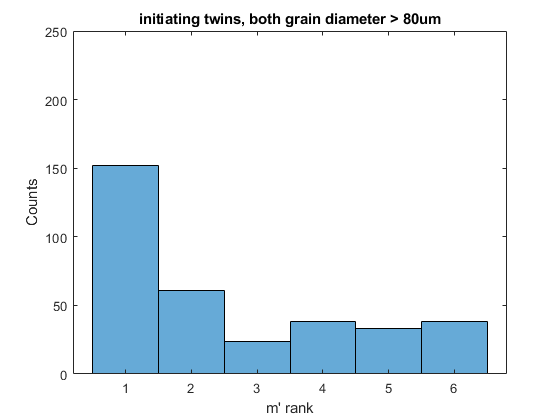

ylim = get(gca,'ylim');

% (4) divide by grain size
ind = (T.incoming==1)&(T.initiating==1)&(T.gDia>100)&(T.gDia_neighbor>100);
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('initiating twins, both grain diameter > 80um');
set(gca,'ylim',ylim);

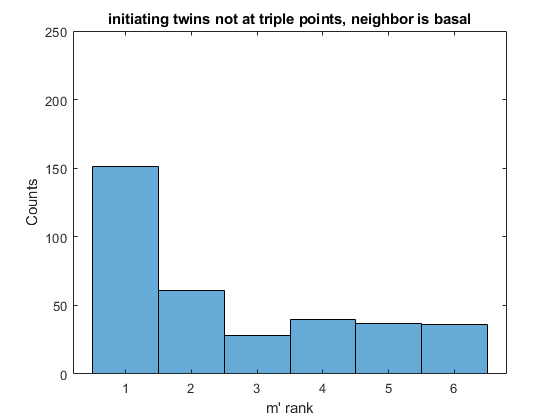


% (5) If only look at those paired with basal slip
ind = (T.incoming==1)&(T.initiating==1)&(ismember(T.ssn_neighbor,[1,2,3]));
t = T(ind,:);
figure;
histogram(t.rank_mPrime, 0.5:6.5);
xlabel('m'' rank');
ylabel('Counts');
title('initiating twins not at triple points, neighbor is basal');
set(gca,'ylim',ylim);

## (3) resB

close all;
% (1) all boundaries, distribution of m'
figure;
histogram(T.resB, 0:0.1:1);
xlabel('resB');
ylabel('Counts');
title('all boundaries, all twins');

% (2) boundaries with intersecting twins
ind = (T.incoming==1);
t = T(ind,:);
figure;
histogram(t.resB, 0:0.1:1);
xlabel('resB');
ylabel('Counts');
title('only intersecting twins');

% (3) boundaries with initiating twins
ind = (T.incoming==1)&(T.initiating==1);
t = T(ind,:);
figure;
histogram(t.resB, 0:0.1:1);
xlabel('resB');
ylabel('Counts');
title('initiating twins');
ylim = get(gca,'ylim');

## (4) resB_rank

close all;
% (1) all boundaries, distribution of m'
figure;
histogram(T.rank_resB, 0.5:6.5);
xlabel('resB rank');
ylabel('Counts');
title('all boundaries, all twins');

% (2) boundaries with intersecting twins
ind = (T.incoming==1);
t = T(ind,:);
figure;
histogram(t.rank_resB, 0.5:6.5);
xlabel('resB rank');
ylabel('Counts');
title('only intersecting twins');

% (3) boundaries with initiating twins
ind = (T.incoming==1)&(T.initiating==1);
t = T(ind,:);
figure;
histogram(t.rank_resB, 0.5:6.5);
xlabel('resB rank');
ylabel('Counts');
title('initiating twins');
ylim = get(gca,'ylim');

## This shows the relationship between m' rank and resB rank.

close all;
colormap parula
edges = 0.5:6.5;
N = zeros(6,6);
for ii = 1:6
    ind = (T.rank_mPrime == ii);
    [N(:,ii),~] = histcounts(T.rank_resB(ind), edges);
end
figure;
bar(1:6, N, 'stacked');
xlabel('resB rank');
ylabel('Counts');
legend({'mPrime rank = 1','mPrime rank = 2','mPrime rank = 3','mPrime rank = 4','mPrime rank = 5','mPrime rank = 6'},'location','bestoutside');

## (5) m' vs neighbor_SF